Let's take a look at the effects of input sauration on convergence.  I'll track a square to guarantee saturation and set a saturation limit.

P = tf(1,[1 1]);
T = 0.1;
Pd = c2d(P,T);
K = 0.5;
umax = 10;

Firstly, let me see the error for a standard feedback controller.

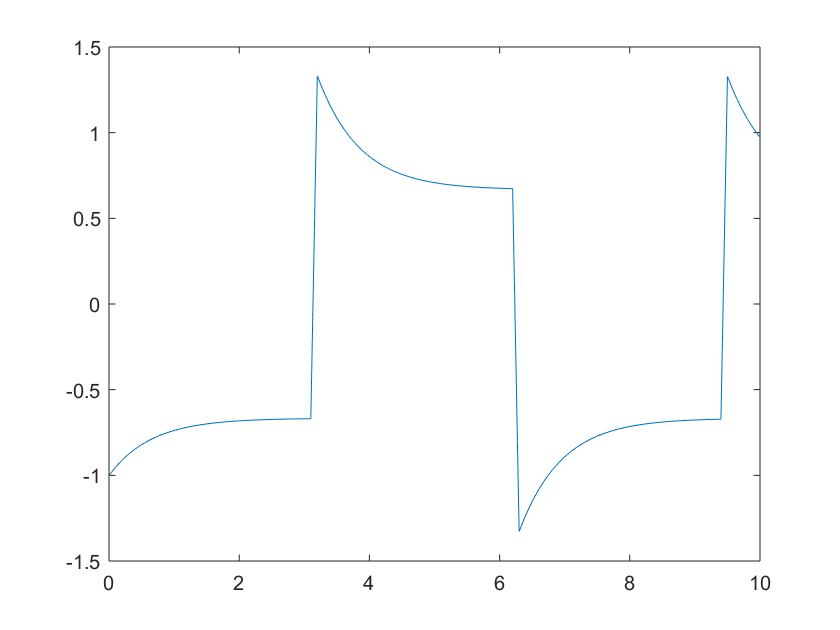

u_ilc = [[0:T:10]' zeros(101,1)];
sim('ILC_Intro_Saturate');
plot(Response(:,1),Response(:,2)-Response(:,3))

I will use the simple ILC update law here: $u_{j+1}(k) = u_j(k)+\alpha e_{j}(k+1) $.  With input saturation, other approaches like $H_\infty$ can be much too agressive.

From before we had that a gain of 2 works well.  I bet we should be more cautious...

alpha = 2;

Now let's run the ILC, but with a slight change.  Much like anti-windup compensation, I want to stop learning when I hit the saturation limit.

u_ilc = [[0:T:10]' zeros(101,1)];
N = 100;  %Number of iterations of ILC

Now let's run ILC using the Simulink model.

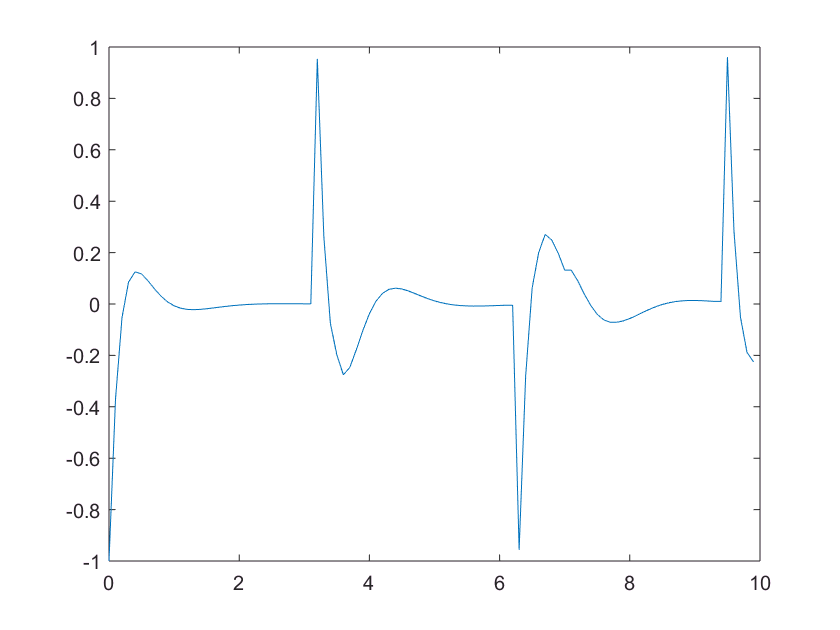

e = [];
for ii = 1:N
    sim('ILC_Intro_Saturate');  %Get the data
    e = [e;std(Response(1:end-1,2)-Response(1:end-1,3))];  %Record error value
    for ii = 1:100
        u_ilc(ii,2) = saturate(u_ilc(ii,2)+alpha*(Response(ii+1,2)-Response(ii+1,3)),umax);  %Implement ILC
    end
end
plot(Response(1:end-1,1),Response(1:end-1,2)-Response(1:end-1,3))

It seems like it might be working!  Now let's plot the error convergence.

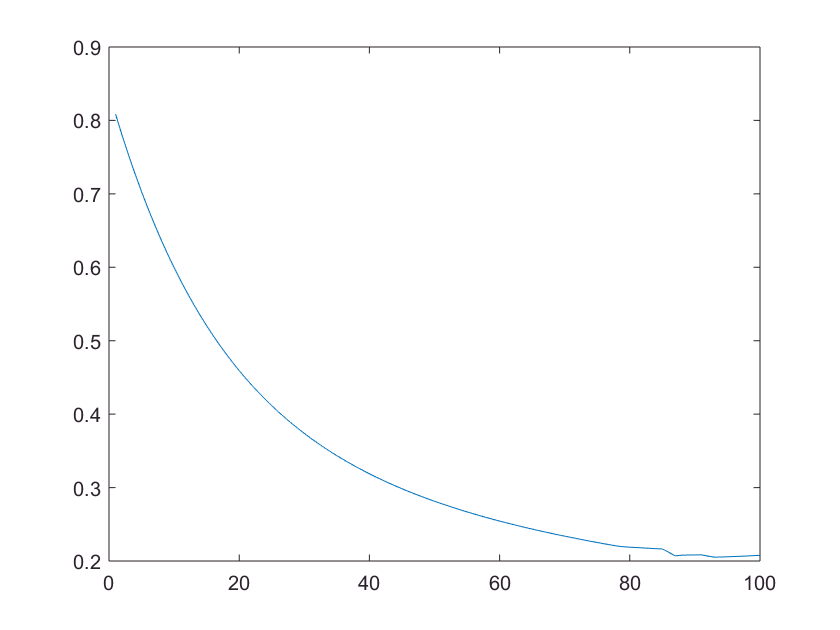

plot(e)

Things can get ugly!  Moral of the story - if saturation is a concern, use a simple update law and use low learning gains!